% ACh sensor dose dependent, 2022.11.22
cd("/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221122_AchsensorHEK001")
load('analysis_offset0_ROIadjusted_20221128_v3_ROIrevision_TopPixels.mat')

% ACh sensor dose dependent, 2022.11.22
cd("/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221122_AchsensorHEK002")
load('analysis_offset0_ROIadjusted_v2_TopPixels.mat')


all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13]; % all the epochs
drug_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

drug_epoch_index = zeros(1,length(drug_epochs));
for i = 1:length(drug_epochs)
    drug_epoch_index(i) = find(all_epochs == drug_epochs(i));
end

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

FLIM_posthoc_analysis_dendrite_HEK_cell_TopPixels

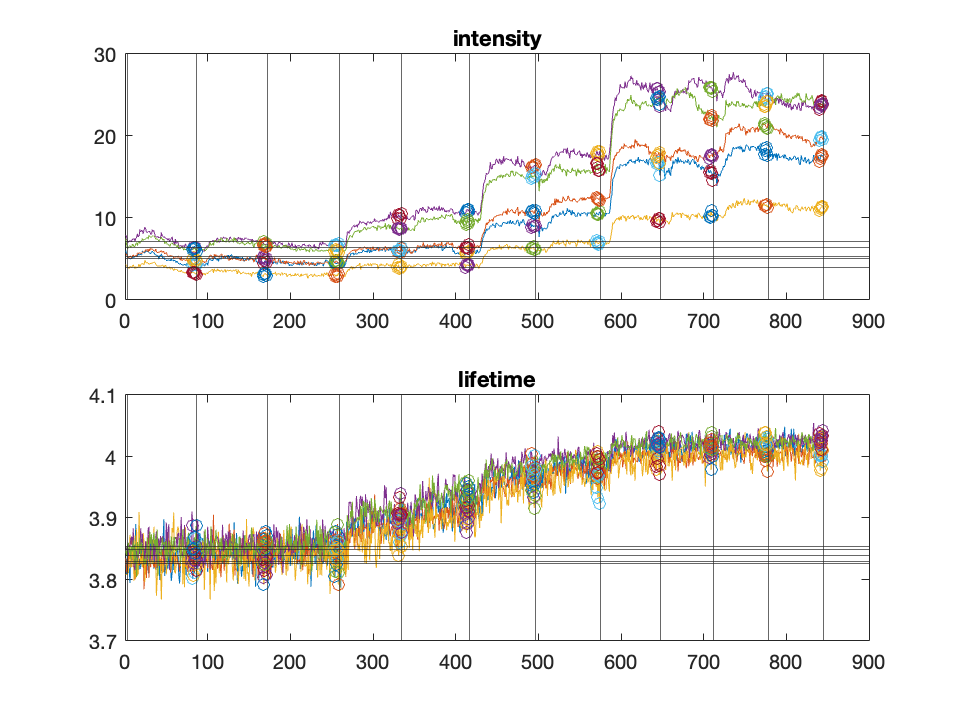

% This section is used for calculation of epoch based response.
% baseline response = baseline_epoch_response - baseline_start;
% other epoch response = epoch_response - baseline_epoch_response;

% calculated response will be included in cell
% epoch_response_intensity_norm_all and cell
% epoch_response_lft_norm_all. Each cell correspond to each cycle
% position.

epoch_response_intensity_norm_all = {};
epoch_response_lft_norm_all = {};

for i_cycle = 1:length(CyclePositions)

    % the intensity and lifetime raw data
    eval(['intensity = intensity{',num2str(CyclePositions(i_cycle)),'};']);
    eval(['lft = lft{',num2str(CyclePositions(i_cycle)),'};']);

    % the epoch transition points
    eval(['EpochStartAcq = EpochStartAcq', num2str(CyclePositions(i_cycle)), ';'])


    % pre-define the epoch response and baseline start
    epoch_response_intensity = zeros(length(drug_epochs)-1,size(intensity, 2));
    epoch_response_lft = zeros(length(drug_epochs)-1,size(lft,2));
    baseline_start_intensity = zeros(1, size(intensity,2));
    baseline_start_lft = zeros(1, size(lft,2));
    
    % the epoch transition index in the raw data of intensity and lft
    drug_epoch_start_acq = EpochStartAcq(all_epochs-1);
    eval(['drug_epoch_start_acq_',num2str(CyclePositions(i_cycle)), '=drug_epoch_start_acq(drug_epoch_index);'])

    
    % calculation of baseline start (mean of the first x acqs)
    for i = 1:size(intensity, 2)
        baseline_start_intensity(i) = mean(intensity(drug_epoch_start_acq(1):drug_epoch_start_acq(1)+baseline_acq_num-1, i));
        baseline_start_lft(i) = mean(lft(drug_epoch_start_acq(1):drug_epoch_start_acq(1)+baseline_acq_num-1, i));
    end
    

    % calculation epoch based response (mean of last x acqs)
    figure;
    subplot(2,1,1);
    plot(intensity)
    yline(baseline_start_intensity)
    xline(drug_epoch_start_acq(drug_epoch_index))
    title('intensity')
    hold on

    for i = 1:size(intensity, 2)
        for j = 1:length(drug_epochs)-1
        epoch_response_intensity(j,i) = mean(intensity((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i));
        scatter((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1), intensity((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i))
        hold on
        end
    end

    hold off

    subplot(2,1,2);
    plot(lft)
%     ylim([3.8 4.15])
    yline(baseline_start_lft)
    xline(drug_epoch_start_acq(drug_epoch_index))
    title('lifetime')
    hold on

    for i = 1:size(intensity, 2)
        for j = 1:length(drug_epochs)-1
        epoch_response_lft(j,i) = mean(lft((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i));
        scatter((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1), lft((drug_epoch_start_acq(drug_epoch_index(j+1))-epoch_acq_num):(drug_epoch_start_acq(drug_epoch_index(j+1))-1),i))
        hold on
        end
    end
    hold off

    saveas(gcf, ['cycle ', num2str(i_cycle),'.fig'])
    saveas(gcf, ['cycle ', num2str(i_cycle),'.png'])
    
    
    epoch_response_intensity_norm = zeros(length(drug_epochs)-1,size(intensity, 2));
    epoch_response_lft_norm = zeros(length(drug_epochs)-1,size(lft,2));
    
    % first raw: baseline change, baseline response - baseline start
    epoch_response_intensity_norm(1,:) = (epoch_response_intensity(1,:) - baseline_start_intensity)./baseline_start_intensity;
    epoch_response_lft_norm(1,:) = epoch_response_lft(1,:) - baseline_start_lft;

    % normalized epoch response. intensity: df/f0; lifetime: minus baseline response
    epoch_response_intensity_norm(2:end,:) = (epoch_response_intensity(2:end,:) - epoch_response_intensity(1,:))./epoch_response_intensity(1,:);
    epoch_response_lft_norm(2:end,:) = epoch_response_lft(2:end,:) - epoch_response_lft(1,:);
    

    epoch_response_intensity_norm_all{CyclePositions(i_cycle)} = epoch_response_intensity_norm;
    epoch_response_lft_norm_all{CyclePositions(i_cycle)} = epoch_response_lft_norm;

end

% calc EC50 if needed
intensity_response_EC50 = zeros(length(drug_epochs)-1,length(baseline_start_intensity));
lft_response_EC50 = zeros(length(drug_epochs)-1,length(baseline_start_intensity));
for i = 1:length(baseline_start_intensity)
    baseline_intensity = baseline_start_intensity(1,i);
    max_response_intensity = max(epoch_response_intensity(:,i));
    intensity_response_EC50(:,i) = (epoch_response_intensity(:,i) - baseline_intensity)/(max_response_intensity - baseline_intensity);
    
    baseline_lft = baseline_start_lft(1,i);
    max_response_lft = max(epoch_response_lft(:,i));
    lft_response_EC50(:,i) = (epoch_response_lft(:,i) - baseline_lft)/(max_response_lft - baseline_lft);
end

% draw a roi of background at ['Z:\Active\Pingchuan\2022Fall\20221029AchsensorHEK001\20221029AchsensorHEK001FLIM005.mat';]
% background roi selection is saved at
% Z:\Active\Pingchuan\2022Fall\20221029AchsensorHEK001\topPMT_background.png

t = Tiff('20221122_AchsensorHEK001010.tif');
imageData = read(t);
imageData = double(imageData);
background = Yao_calc_Projection(imageData, gui.gy.rois{1,1}.mask);
num_img = 820;
acq_start = 3;
base_name = '20221122_AchsensorHEK001';
tiff_images = {};

% draw a roi of background at ['Z:\Active\Pingchuan\2022Fall\20221029AchsensorHEK001\20221029AchsensorHEK001FLIM005.mat';]
% background roi selection is saved at
% Z:\Active\Pingchuan\2022Fall\20221029AchsensorHEK001\topPMT_background.png

t = Tiff('20221122_AchsensorHEK002010.tif');
imageData = read(t);
imageData = double(imageData);
background = Yao_calc_Projection(imageData, gui.gy.rois{1,1}.mask);
num_img = 846;
acq_start = 2;
base_name = '20221122_AchsensorHEK002';
tiff_images = {};


for i = acq_start:num_img
    if i<10
        t = Tiff([base_name, '00', num2str(i), '.tif'], 'r');
    else if i>=10 & i<=99
            t = Tiff([base_name, '0', num2str(i), '.tif'], 'r');
        else
            t = Tiff([base_name, num2str(i), '.tif'], 'r');
        end
    end
    
    imageData = read(t);
    imageData = double(imageData);
    imageData = imageData - background;
    tiff_images{i-acq_start+1,1} = imageData;
end


intensity1_top = zeros(num_img-acq_start+1, size(stateYao.ROI{1,1}{1},2));

for i = 1:size(stateYao.ROI{1,1}{1},2)
    for j = 1:num_img-acq_start+1
        I_mask = stateYao.I_ROI_stack_TopPixels{1,1}{1,j}{i};
        projection = Yao_calc_Projection(tiff_images{j,1}, I_mask);
        intensity1_top(j,i) = projection;
    end
end